% =============================================
% RMS DELAY SPREAD CALCULATION FROM CIR (Real Measurements)
% =============================================

%clc; clear; close all;

%% Load CIR Data (Replace with your data)
% Format: h = [sample1; sample2; ...; sample281] (complex or real)
% Example: Synthetic CIR with 3 multipath components + noise
N = 281;                    % Number of samples
dt = 1e-10;                  % Sampling interval 
t = (0:N-1)' * dt;          % Time vector

% Synthetic CIR (replace with your measured data)
% h = zeros(N,1);
% h(50) = 0.8 + 0.2j;         % First path (strongest)
% h(70) = 0.3 - 0.5j;         % Second path
% h(120) = 0.1 + 0.1j;        % Third path
% h = Final_response';%h + 0.05*(randn(N,1) + 1j*randn(N,1)); % Add noise

i = 4

i = 4

h_rec = extractedCIRNorm_noise;%MeanCIRog(i,:)';


%% Step 1: Compute Power Delay Profile (PDP)
P = abs(h_rec).^2;              % Power in linear scale

%% Step 2: Noise Thresholding
threshold_percent = 0.03;     % 10% of peak power threshold
threshold = threshold_percent * max(P);
valid_indices = P >= threshold;
P_clean = P(valid_indices);
tau_clean = t(valid_indices); % Delays of valid components

%% Step 3: Calculate RMS Delay Spread
if sum(P_clean) > 0
    mean_tau = sum(P_clean .* tau_clean) / sum(P_clean);
    mean_tau_sq = sum(P_clean .* tau_clean.^2) / sum(P_clean);
    rms_delay = sqrt(mean_tau_sq - mean_tau^2);
else
    error('Threshold too high: No valid multipath components detected.');
end

%% Display Results
fprintf('===== Results =====\n');

===== Results =====


fprintf('Sampling Interval (dt): %.2f ns\n', dt*1e9);

Sampling Interval (dt): 0.10 ns


fprintf('Mean Excess Delay: %.2f ns\n', mean_tau*1e9);

Mean Excess Delay: 7.17 ns


fprintf('RMS Delay Spread: %.2f ns\n', rms_delay*1e9);

RMS Delay Spread: 0.75 ns


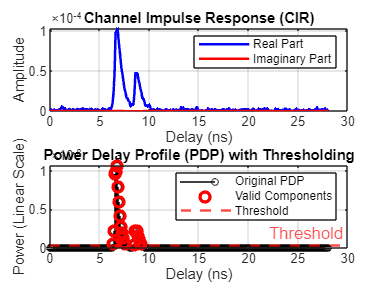


%% Visualization
figure;

% Plot CIR (Real and Imaginary Parts)
subplot(2,1,1);
plot(t*1e9, real(h_rec), 'b', 'LineWidth', 1.5); hold on;
plot(t*1e9, imag(h_rec), 'r', 'LineWidth', 1.5);
xlabel('Delay (ns)');
ylabel('Amplitude');
title('Channel Impulse Response (CIR)');
legend('Real Part', 'Imaginary Part');
grid on;

% Plot PDP with Threshold
subplot(2,1,2);
stem(t*1e9, P, 'k', 'MarkerSize', 4, 'LineWidth', 0.5); hold on;
plot(tau_clean*1e9, P_clean, 'ro', 'MarkerSize', 6, 'LineWidth', 2);
yline(threshold, '--r', 'Threshold', 'LineWidth', 1.5);
xlabel('Delay (ns)');
ylabel('Power (Linear Scale)');
title('Power Delay Profile (PDP) with Thresholding');
legend('Original PDP', 'Valid Components', 'Threshold');
grid on;